**Time Dissemination**

**Background**

White rabbit is a time dissemination protocol which incorporates PTP and SyncE network architecture with subnanosecond accuracy. In a white rabbit network, time is distributed in layers named stratum

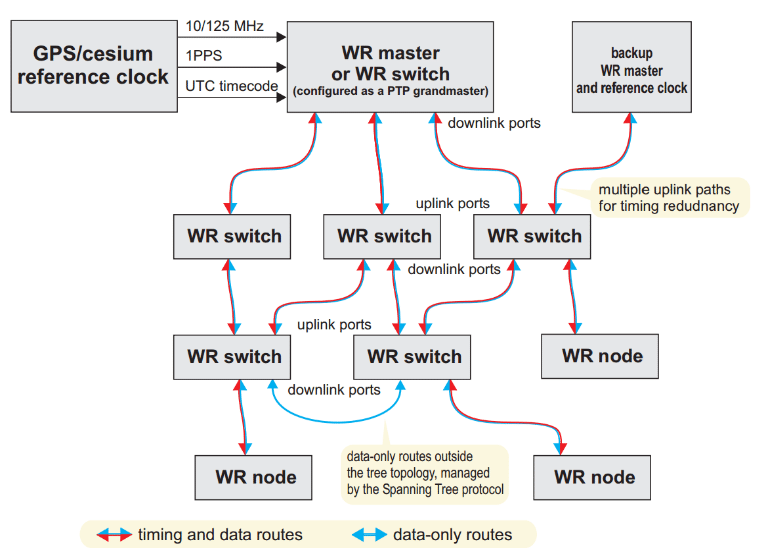

(Tomasz Wlostowski 2010)

A white rabbit grandmaster synchronises with a reference clock (usually an atomic clock) and distribues frequency via SyncE and time via PTP with boundary clocks (denotes in the diagram as WR Switches) which behave as slaves to the grandmaster and masters to clocks on lower stratum levels. Finally the consumers recieve the distributed times (denoted as WR node) from the boundary clocks.

**How is time distributed between a WR master and slave**

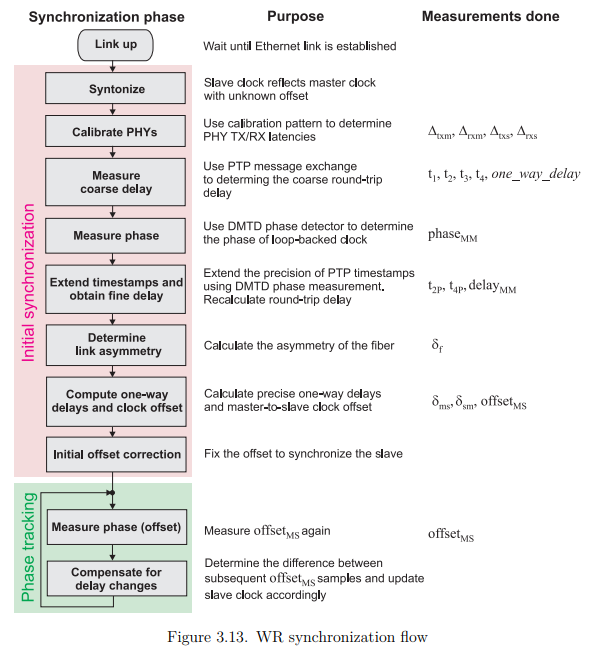

(Tomasz Wlostowski 2010)

The following code will mainly focus on modelling initial synchronisation between a slave and master clock. Later sections will talk about phase tracking.

**Inital Synchronisation**

Before the white rabbit protocols are ran a link must be established between the white rabbit master clock and the slave. White rabbit requires specialised hardware to compose the white rabbit switches for time stamping. The specialised hardware is designed to timestamp packets of data at the physical level which minimises time stamping uncertainty and clock jitter.

Once a link as been established the white rabbit timing process distibutes time to slave clocks

- **SyncE: **SyncE PLL system is used to syntonise the frequency of the master and slave of time.

- **Calibration: **Packets are time stamped at the hardware level which have deterministic latency values $\Delta_1, \Delta_2, \Delta_3, \Delta_4$. These latency values will be taken into account when considering round-way trips of packets.

- **PTP:** A PTP message chain synchronises clock time.

- **Correction: **The master and slave have the same frequency but are out of phase by $\phi$which will be determined by a Digital Dual Mixer Time Difference (DDMTD) phase detector. The PTP values will be adjusted to account for the phase difference and calculate the offset in time between the slave and master.

**SyncE Simulation**

Synchronous Ethernet (SyncE) is a technology used to disseminate clock frequency. As opposed to standard ethernet which syntonises frequency using free oscillator, SyncE uses Phase-Locked Loops (PLL) to lock oscillators to the required frequency. White rabbit uses a heirarchical SyncE network with PLL oscillators distributing frequency to client clocks below them.

A Phase-Locked Loop attempts to match the frequency of the slave with the master by correcting any deviation from the master frequency. A basic PLL have the following modules:

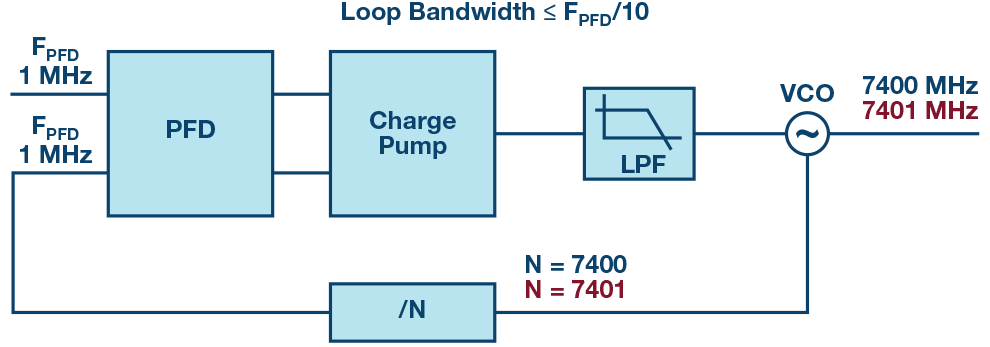

(Ian Colins 2018)

- The master $f_M$ and slave frequency $f_S$ are sent into a phase detector. The error between the frequencies is measures as $f_{error}=f_{S}-f_{M}$.

- A charge pump injects a phase $\phi_{corr}$ to correct the frequency of the slave and match it with the master.

- The low pass filter reduces the noise and jitter frequencies $f_M, \ f_S$.

- The VXCO is the slave oscillator that adjusted by the $\phi_{corr}$ to match closely with the master frequency.

- The new freqency is then passed through the phase detector again in a feedback loop.

The PLL system will allow a slave to match the frequency of the master with some fixed offset phase $f_{offset}$.

Below is a simulation of a PLL system using the *Clock_Simulator.m.*

Refer to *SyncE_Simulator.m* to see how the simulation mimics a PLL system.

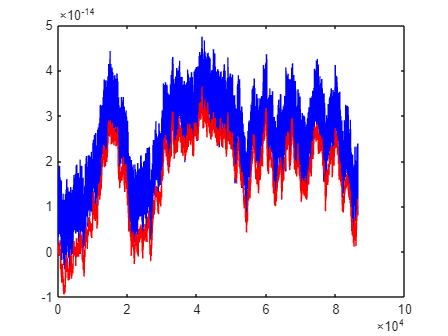

clear

% Set tick sizes.

N=86400;
t=1;

% Master and slave clock parameters.

% Master/Slave diffusion coefficients.

diff_master=Diffusion_Coefficient_Estimator((10^-13)^2,(10^-15)^2,1,10^3,0);
diff_slave=Diffusion_Coefficient_Estimator((5*10^-11)^2,(10^-12)^2,1,10^3,0);

% Master/Slave initial values.

X0_master=[0,0,10^-22];
X0_slave=[0,0,10^-13];

% Packet loss transition matrix.

P=[0.999 0.001 ; 0.1 0.9];

% Master frequency clock simulation.

[~,MasterFreq]=Clock_Simulator(N,t,X0_master,diff_master,[0,0,0]);

% SyncE simulation syntonises slave clock frequency.

SlaveFreq=SyncE_Simulator(N,t,MasterFreq,X0_slave,diff_slave,[0,0,0],0.90,0.1,P);


% Plot master and slave frequencies.

plot(1:N/t+1,SlaveFreq,'b')
hold on
plot(1:N/t+1,MasterFreq,'r')
hold off

Notice that there exists some offset $f_{offset}$. White rabbit correct for the offset using DDMTD module later on.

**PTP Simulation**

Precision Timing Protocol (PTP) is a sync algorithm to synchronise a master and slave clock through a message communication chain between the clocks demonstrated below

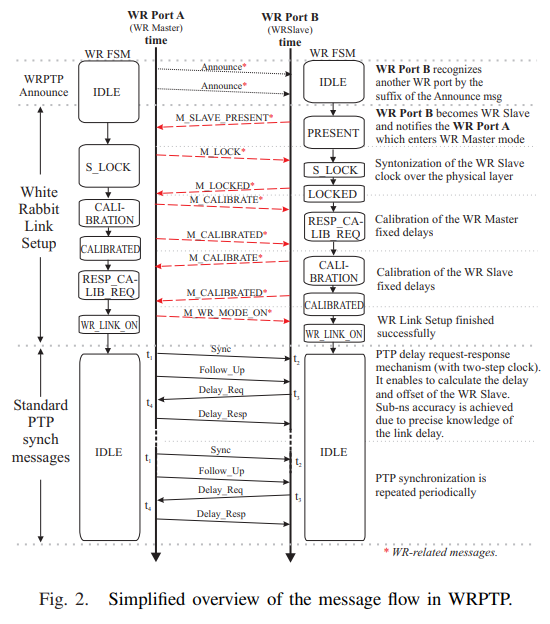

(M. Lipinski et al 2011)

When considering a white rabbit network, after inital white rabbit calibration for fixed physical time stamping delays and SyncE syntonisation, PTP is employed to synchronise slave time with the master time. The PTP message exchange algorithm is executed in the following way

- **Announcement:** The master announces the PTP protocol. The usual sync interval between successive announcements for PTP is 20 seconds.

- **Sync_Message:** The master sends a sync message at time $t_1$ and after a delay time $\delta_{ms}$ the slave recieves the message at $t_2$. In PTPv2 a Follow_Up message is sent to the slave carrying $t_1$ information to the slave.

- **Delay_Req:** After the slave recieves the sync message a delay_request message is sent from the slave at $t_3$ and recieved by the master at $t_4$ after $\delta_sm$ delay time. A Delay_Resp message is sent to the slave carrying the information of $t_4$.

- The two-way round-trip time is calculated as


$$delay_{mm}=(t_4-t_1)-(t_3-t_2)$$


          5.** Asymmetry:** White rabbit considers the asymmetry between $\delta_{ms}$ and $\delta_{sm}$. The one-way trip delay time is estimated as 


$$delay_{ms}=\bigg(\frac{1+\alpha}{2+\alpha}\bigg)delay_{mm} \ \text{where} \ \alpha=\frac{\delta_{ms}}{\delta_{sm}}-1.$$


            Note: With the assumption of true symmetry $\delta_{sm}=\delta_{ms} \Rightarrow \alpha=0$ which is the usual assumption with PTP.

          6. Offset**:** The offset of the slave from the master is

$\theta=t_2-t_1-delay_{ms}$.

The following is a simulation of a white rabbit message exchange using SyncE and PTP.

Refer to *PTP_Simulator.m *and *White_Rabbit_Simulator.m.* 

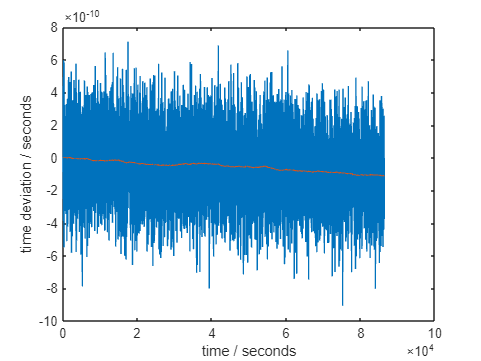

clear;

% Set tick size.

N=86400;
t=1;

% Master Clock time and frequency.

diff_master=Diffusion_Coefficient_Estimator(10^-26,10^-30,1,10^5,0);
[master_time,master_freq,~]=Clock_Simulator(N,t,[0,0,10^-22],diff_master,[0,0,0]);

% Slave clock parameters.

slave_clock=[0,0,10^-13,2.5*10^-21,1,10^-24,10^3,0,0,0];

% White Rabbit uses SyncE and PTP to ensure slave time synchronicity.

[slave_time,slave_freq]=White_Rabbit_Simulator(N,t,master_time,master_freq,slave_clock,0.95,0.01,20,1000,0.9*3*10^8,[1 , 0 ; 0.1 , 0.9]);

% Plot master and slave times.


plot(1:N/t+1,slave_time)
hold on
plot(1:N/t+1,master_time)
hold off

xlabel('time / seconds')
ylabel('time deviation / seconds')

**Packet Delay Models**

The delay model considered for SyncE and PTP is the Gilbert-Elliot model. The model is modelling packet loss for messages sent by the SyncE and PTP protocols. This model is a stochastic two-state Markov chain model which considers a successive state and a failed state. This model is particularly useful for modelling burst packet loss and holdover time for the slave clocks.

(G. Hasslinger& O. Hohlfeld 2010)

**Electronically Stabilised Fibre Optic Transfer (ELSTAB)**

**Background**

ELSTAB solution was devloped by AGH University of Science and Technology for time and frequenecy dissemination. The solution uses a delay-lock loop and the low uncertainty of optical fibre to disseminate time and frequency from a local clock module that acts as a reference to a remote clock module.

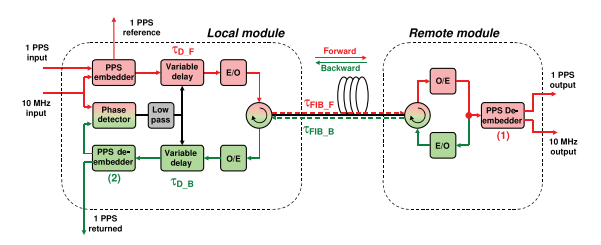

(Przemysław Krehlik et al 2015)

A signal is input into the local module and converted by an electrical-optical converter to be sent over a fibre optic system. The signal is recieved by the remote module and sent back to the local module. The initial input and the recieved signal is compared by a phase detector and a variable delay shifts the delay line so that the two-way delay between the signals are such that


$$two\_way\_delay=\tau_{D_F}+\tau_{FIB_F}+\tau_{FIB_B}+\tau_{D_B}=const.$$


**Delay-Lock Loop (DLL)**

As previously established, the delay-lock loop helps to correct any noise variation in delay time between an input signal from a reference clock and the signal sent to the remote module. This allows for the $two\_way\_delay$ to remain relatively constant. Under the assumption of symmetry in the forwards and backwards direction


$$one\_way\_delay=\frac{1}{2} \times  two\_way\_delay$$


There is optical asymmetry in the delay time due to noise, chromatic dispersion, temperature differentials. Under ideal conditions, this delay asymmetry may be reduced to a few picoseconds.

Denote the phase difference function between the local signal and the remote signal as $f(t)$. The error in phase difference is

$e(t)=\frac{df}{dt}dt$.

Discretizing time $t_1<t_2<...<t_{n+1}$ with equally spaced time interval the noise in the delay $\delta(t)$ can be written as


$$\delta_i=\alpha \cdot e_i+\beta \cdot f_{i-1}$$


where $\alpha, \beta$ are gain coefficients. The corrected phase is therefore 


$$\phi^{corr}_{i}=\phi^{local}_{i}+\delta_i$$


This locks the phase of the local and remote clocks by a constant delay.

Refer to *ELSTAB_Simulator.m *to simulate a DLL system to disseminate time over fibre optics.

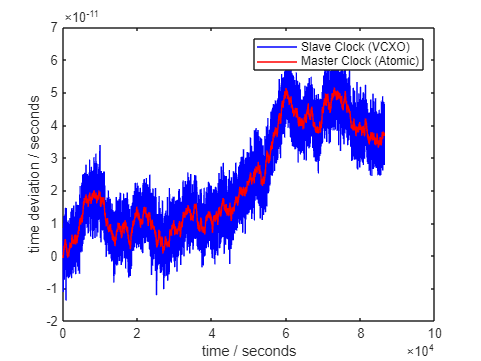

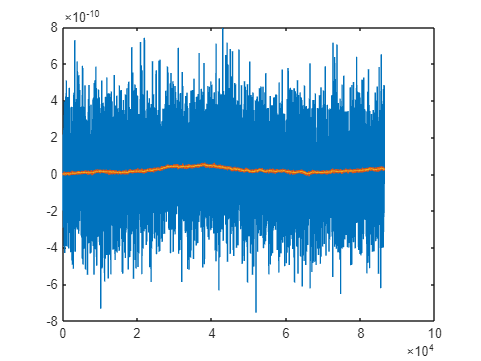

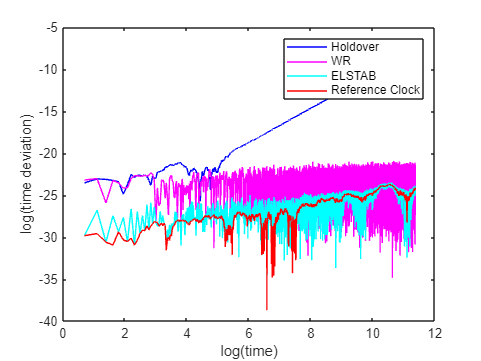

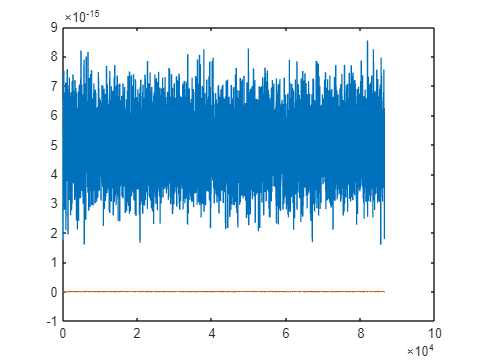

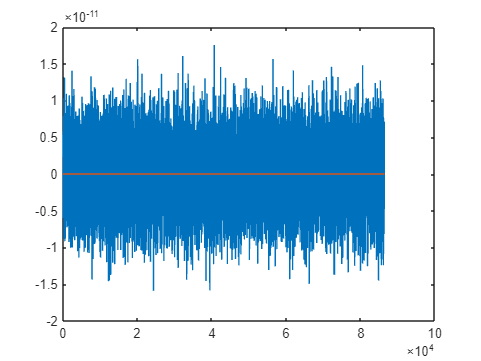

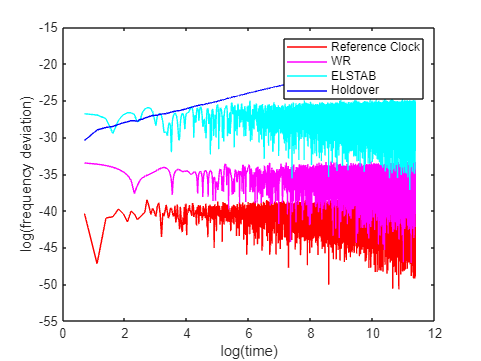

clear

N=86400;
t=1;

Master_Clock=Clock_Type({1,'Caesium'});

[Slave_Time_ELSTAB,~,~,Master_Time]=ELSTAB_Simulator(N,t,Master_Clock,10^-4,10*10^-12,0.999,0.999,0.1,300*10^3,0.66*3*10^8);

plot(Slave_Time_ELSTAB,'b')
hold on

plot(Master_Time,'r')
hold off

ylabel('time deviation / seconds')
xlabel('time / seconds')
legend('Slave Clock (VCXO)', 'Master Clock (Atomic)')